二维图绘制

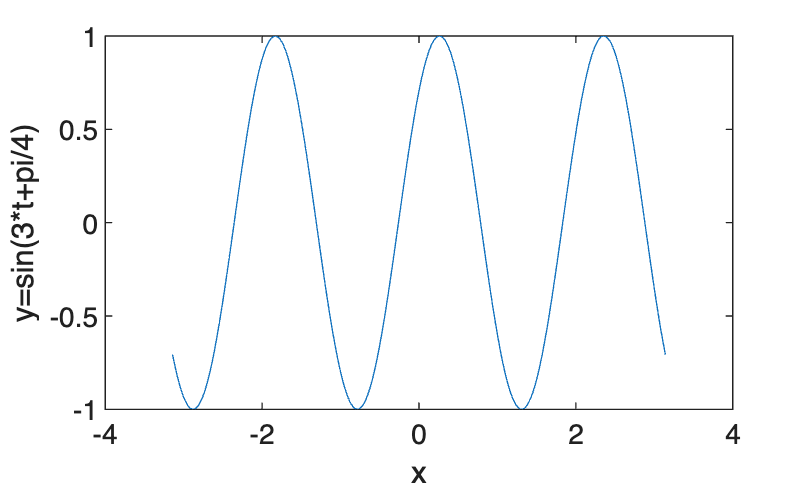

t = -pi:pi/100:pi;
y = sin(3*t+pi/4);
plot(t,y);
xlabel('x');
ylabel('y=sin(3*t+pi/4)');

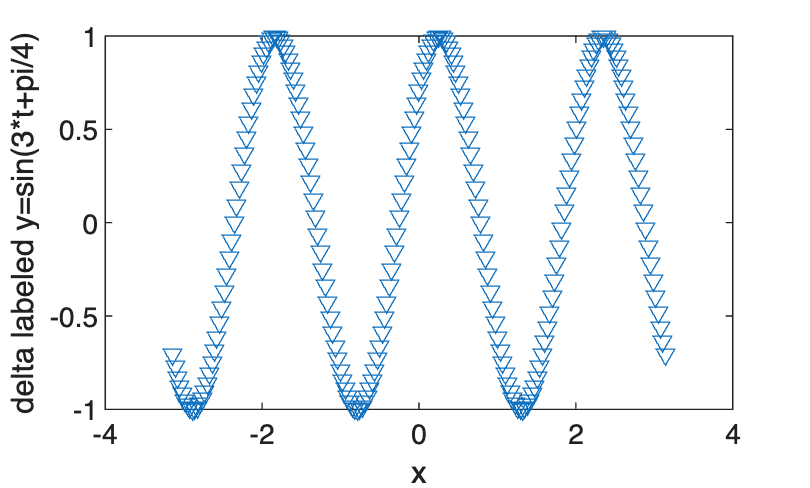

figure  
plot(t,y,'v')
xlabel('x');
ylabel('delta labeled y=sin(3*t+pi/4)');

三维图绘制

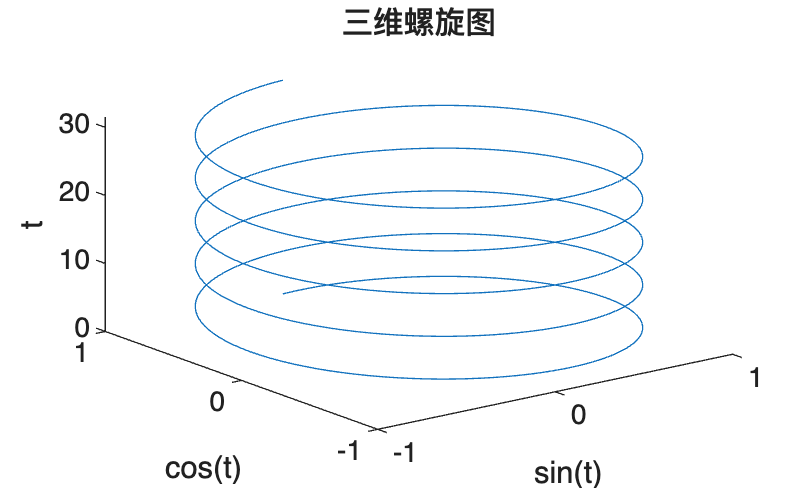

t = 0:pi/50:10*pi;   % t 是由 0 到 10π 的向量，步长为 π/50
st = sin(t);         % st 是 t 的正弦函数
ct = cos(t);         % ct 是 t 的余弦函数

% 绘制三维螺旋图
plot3(st, ct, t);
xlabel('sin(t)');
ylabel('cos(t)');
zlabel('t');
title('三维螺旋图');

图形裁剪

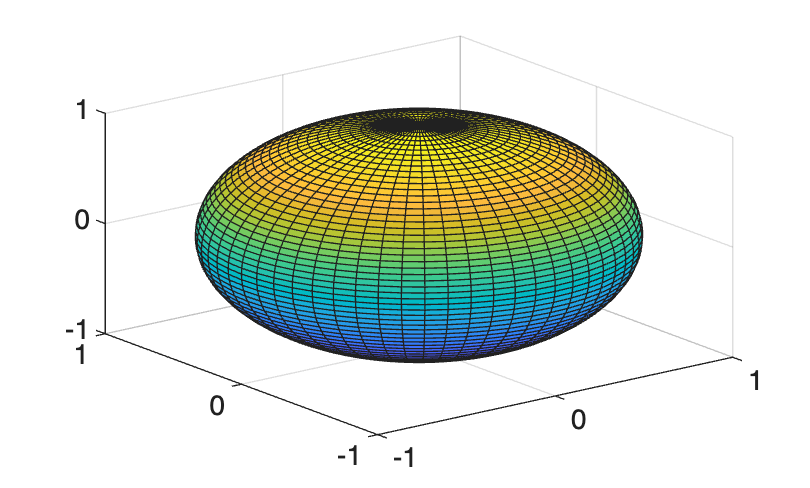

clc
clear all
[x,y,z] = sphere(60);
surf(x,y,z);

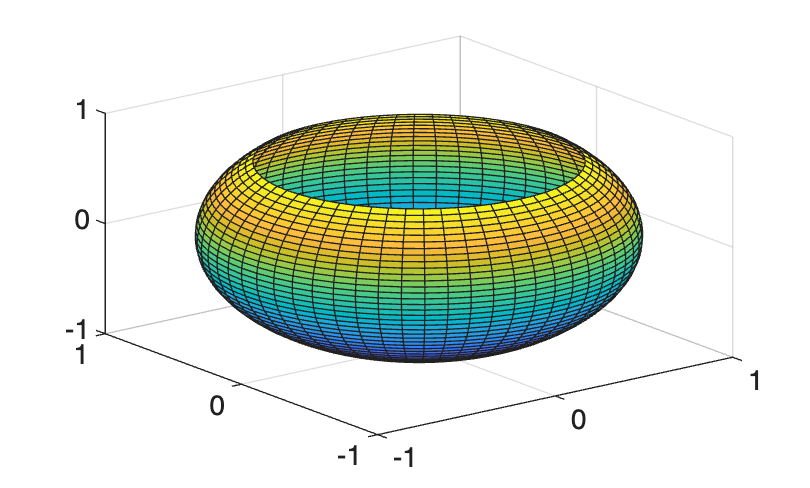

p = z>0.7; z(p) = NaN;
figure; surf(x,y,z);
axis([-1,1,-1,1,-1,1])

标量场的梯度和箭头图绘制

clc
clear all
syms x y
f = x^2*y^3;
g = gradient(f);

通过数值解来计算梯度

[x,y] = meshgrid(-3:.3:3,-3:.3:3);
f = x.^2.*y.^3;
[px,py] = gradient(f)

px =    46.1700   43.7400   38.8800   34.0200   29.1600   24.3000   19.4400   14.5800    9.7200    4.8600         0   -4.8600   -9.7200  -14.5800  -19.4400  -24.3000  -29.1600  -34.0200  -38.8800  -43.7400  -46.1700
   33.6579   31.8865   28.3435   24.8006   21.2576   17.7147   14.1718   10.6288    7.0859    3.5429         0   -3.5429   -7.0859  -10.6288  -14.1718  -17.7147  -21.2576  -24.8006  -28.3435  -31.8865  -33.6579
   23.6390   22.3949   19.9066   17.4182   14.9299   12.4416    9.9533    7.4650    4.9766    2.4883         0   -2.4883   -4.9766   -7.4650   -9.9533  -12.4416  -14.9299  -17.4182  -19.9066  -22.3949  -23.6390
   15.8363   15.0028   13.3358   11.6689   10.0019    8.3349    6.6679    5.0009    3.3340    1.6670         0   -1.6670   -3.3340   -5.0009   -6.6679   -8.3349  -10.0019  -11.6689  -13.3358  -15.0028  -15.8363
    9.9727    9.4478    8.3981    7.3483    6.2986    5.2488    4.1990    3.1493    2.0995    1.0498         0   -1.0498   -2.0995   -3.1493   -4.1990 

py =    65.8530   53.3409   42.1459   32.2680   23.7071   16.4632   10.5365    5.9268    2.6341    0.6585         0    0.6585    2.6341    5.9268   10.5365   16.4632   23.7071   32.2680   42.1459   53.3409   65.8530
   59.2920   48.0265   37.9469   29.0531   21.3451   14.8230    9.4867    5.3363    2.3717    0.5929         0    0.5929    2.3717    5.3363    9.4867   14.8230   21.3451   29.0531   37.9469   48.0265   59.2920
   46.8990   37.9882   30.0154   22.9805   16.8836   11.7248    7.5038    4.2209    1.8760    0.4690         0    0.4690    1.8760    4.2209    7.5038   11.7248   16.8836   22.9805   30.0154   37.9882   46.8990
   35.9640   29.1308   23.0170   17.6224   12.9470    8.9910    5.7542    3.2368    1.4386    0.3596         0    0.3596    1.4386    3.2368    5.7542    8.9910   12.9470   17.6224   23.0170   29.1308   35.9640
   26.4870   21.4545   16.9517   12.9786    9.5353    6.6218    4.2379    2.3838    1.0595    0.2649         0    0.2649    1.0595    2.3838    4.2379 

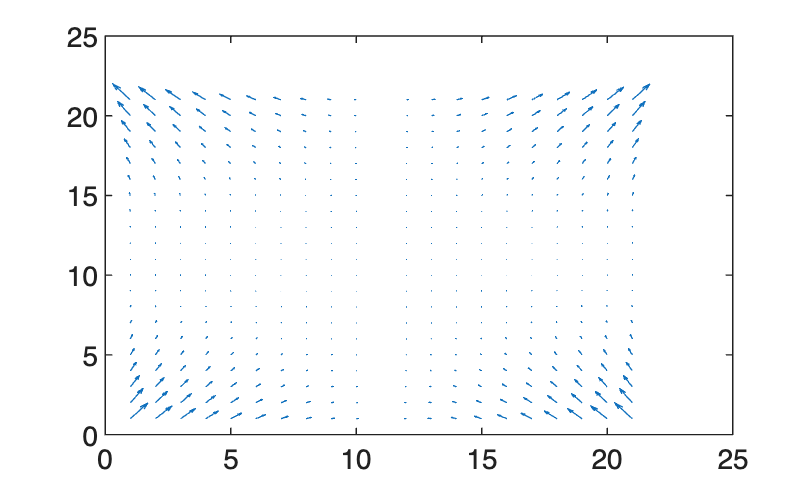

quiver(px,py)

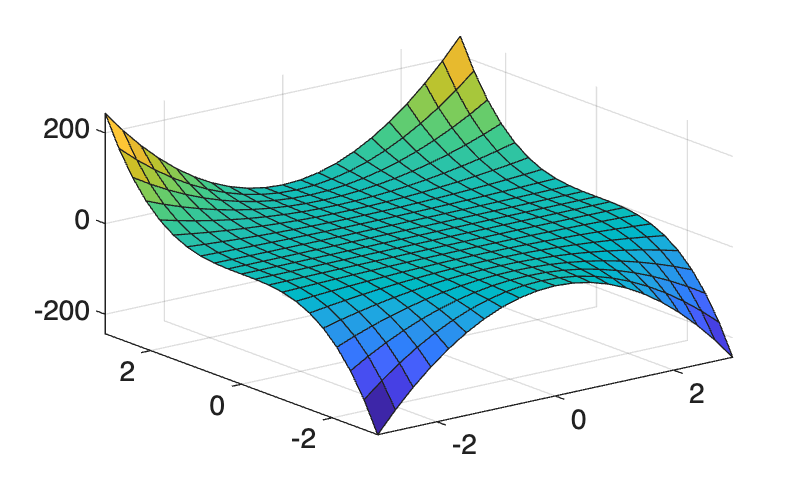

surf(x,y,f)

矢量的流线绘制和散度

[x,y] = meshgrid(0:0.1:1,0:0.1:1);
u = x;
v = -y;
figure
quiver(x,y,u,v)
startx = 0.1:0.1:1;
starty = ones(size(startx))

starty =      1     1     1     1     1     1     1     1     1     1


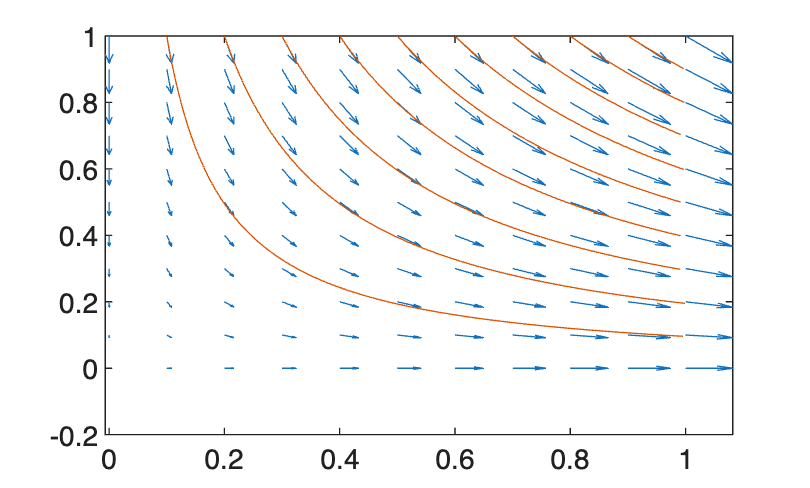

streamline(x,y,u,v,startx,starty)

散度绘制

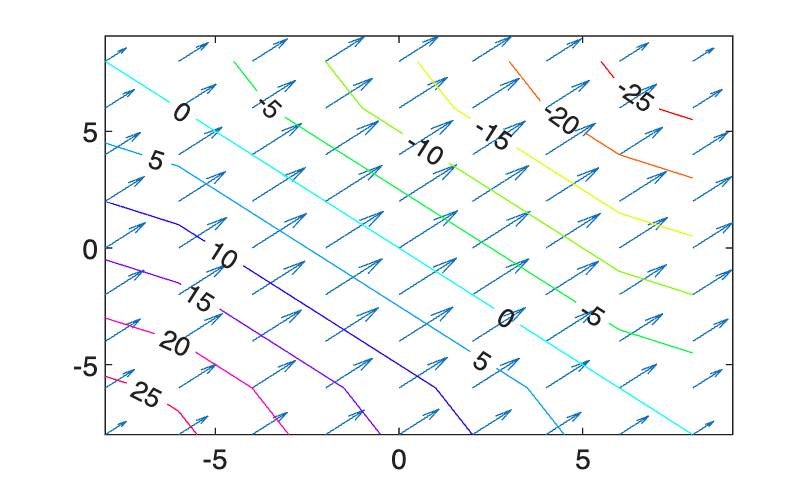

[x,y] = meshgrid(-8:2:8, -8:2:8);   % 生成 9×9 的等距网格，x、y ∈ [-8,8]，步长 2
Fx = 200 - (x.^2 + y.^2);           % 计算矢量场的 x 分量
Fy = 200 - (x.^2 + y.^2);           % 计算矢量场的 y 分量（与 Fx 相同）
quiver(x,y,Fx,Fy)                   % 用箭头可视化该矢量场
D = divergence(x,y,Fx,Fy);         % 计算二维散度 ∇·V = ∂Fx/∂x + ∂Fy/∂y
hold on
contour(x,y,D,'ShowText','on')     % 将散度画成带数值标签的等高线，叠在上层
hold off

散度的流管显示

1）加载数据并计算所需的值

clc
clear all

load wind
xmin = min(x(:)); %流管起点的最小x值
xmax = max(x(:)); ymin = min(y(:)); 
alt = 7.356;
wind_speed = sqrt(u.^2 + v.^2 + w.^2);

2）绘制切片平面

hslice = slice(x,y,z,wind_speed,xmax,ymin,alt)

hslice =   3×1 Surface 数组:

  Surface
  Surface
  Surface


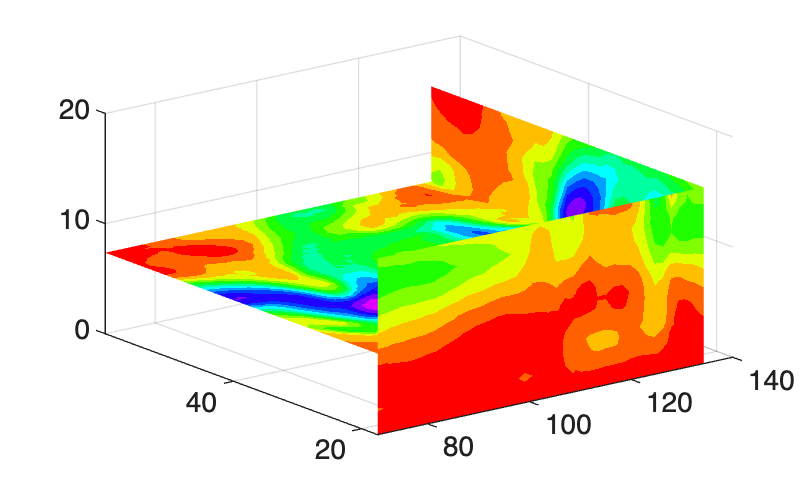

set(hslice,'FaceColor','interp','Edgecolor','none')
colormap hsv(16)

3）在切片平面上添加等高线

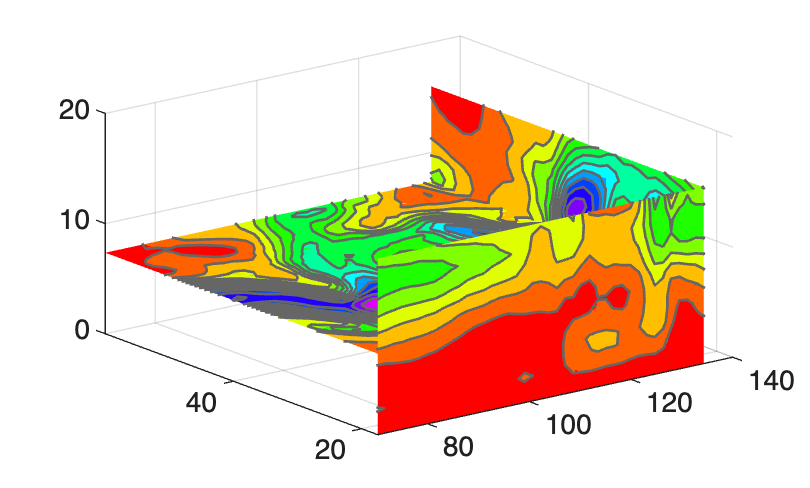

color_lim = caxis;                 % 获取当前坐标系的颜色范围
cont_intervals = linspace(color_lim(1), color_lim(2), 17);
hcont = contourslice(x, y, z, wind_speed, ...
                     xmax, ymin, alt, ...
                     cont_intervals, 'linear');
set(hcont, 'EdgeColor', [.4 .4 .4], 'LineWidth', 1);

4)创建流管

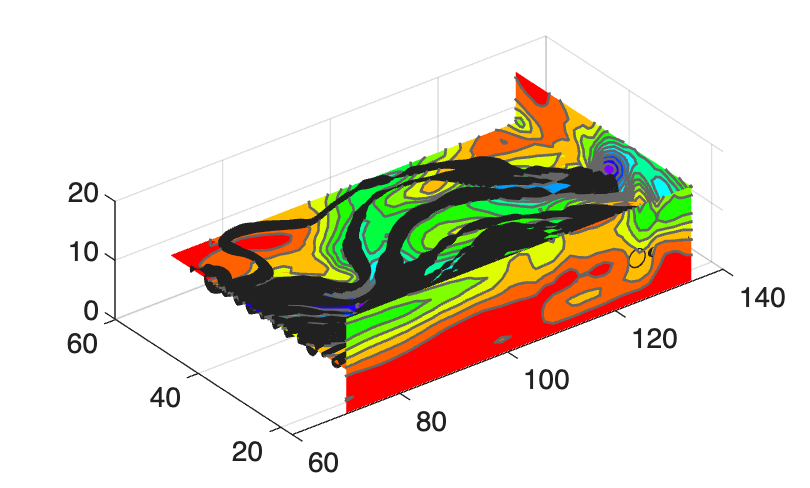

[sx,sy,sz] = meshgrid(xmin,20:3:50,alt);
daspect([1,1,1])%设置数据纵横比
htubes = streamtube(x,y,z,u,v,w,sx,sy,sz,[1.25 30]);

5）定义视图

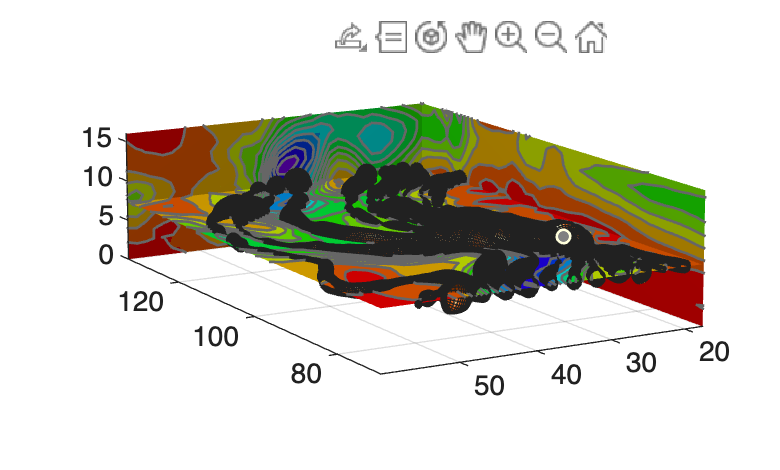

view(-100,30)
axis(volumebounds(x,y,z,wind_speed))
set(gca,'Projection','perspective')
camlight left

矢量的旋度表示

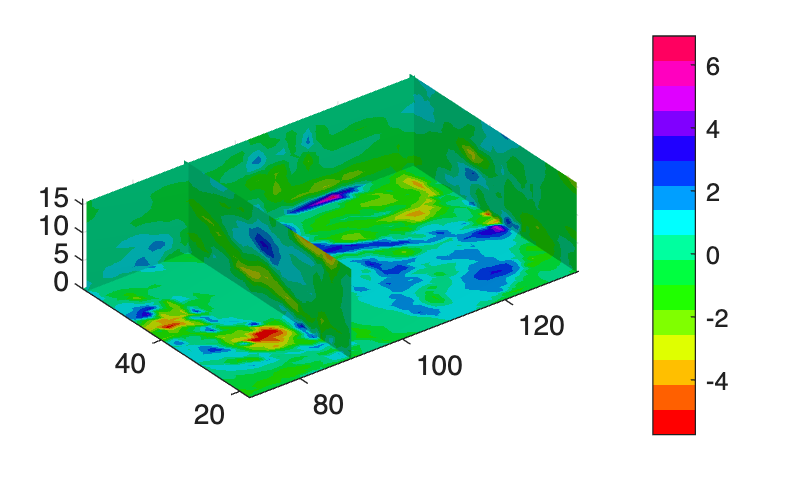

load wind    %加载风场的三维矢量场数据集,包含大小为 35×41×15 的数组
[curlx,curly,curlz,cav]=curl(x,y,z,u,v,w);    %计算矢量场的数值旋度
h=slice(x,y,z,cav,[90 134],59,0);
shading interp
colorbar
daspect([1 1 1]);
axis tight
camlight
set([h(1),h(2)],'ambientstrength',0.6);

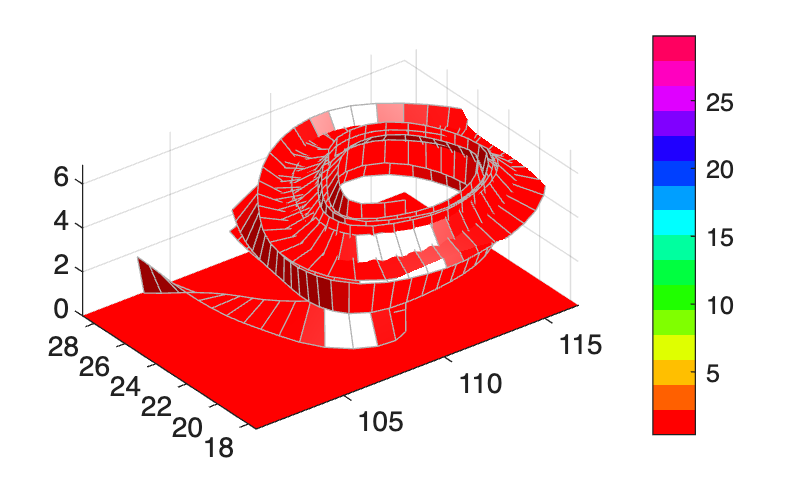

load wind
lims = [100.64 116.67 17.25 28.75 -0.02 6.86];

[x,y,z,u,v,w] = subvolume(x,y,z,u,v,w,lims);
cav = curl(x,y,z,u,v,w);
wind_speed = sqrt(u.^2 + v.^2 + w.^2);
[sx,sy,sz] = meshgrid(110,20:5:30,1:5); % 创建流带的起点数组
verts = stream3(x,y,z,u,v,w,sx,sy,sz,.5); % 以 0.5 为步长计算流线顶点
h = streamribbon(verts,x,y,z,cav,wind_speed,2);
set(h,'FaceColor','r','EdgeColor',[.7 .7 .7],'AmbientStrength',.6)
axis(volumebounds(x,y,z,wind_speed)) % 设置 axis 和颜色
grid on
view(3)
camlight right; % 在视点右侧创建光源，将光照方法设置为 Gouraud